# REPRESENTACIÓN DE PROPIEDADES DE SOFA

## OBTENCIÓN DE DATOS DE SOFA

clear all all

% Desglosamos los valores en sus respectivas componentes
[vector_tiempo,posicion_nodo_0_dcha,posicion_nodo_28_central,posicion_nodo_56_izq] = readvars('properties_0-28-56_x_18.5.txt');

 % Expresion que ayuda a dividir la celda cada que encontramos un espacio en el vector
expression = ' ';

% Dividimos la cadena en la misma variable pero con celdas separadas según
% hemos indicado en la variable expresión. Es decir que ashora por cada
% fila tendremos a su vez una celda dividida en 7 celdas más pequeñas
posicion_nodo_0_dcha_split = regexp(posicion_nodo_0_dcha,expression,'split');
posicion_nodo_28_central_split = regexp(posicion_nodo_28_central,expression,'split');
posicion_nodo_56_izq_split = regexp(posicion_nodo_56_izq,expression,'split');

% Recolectamos los datos y los metemos en una matriz
for i=1:length(posicion_nodo_0_dcha_split)
    
    % Guardamos el valor de la celda en una variable
    posicion_nodo_0_dcha_split_ = posicion_nodo_0_dcha_split{i,1};
    posicion_nodo_28_central_split_ = posicion_nodo_28_central_split{i,1};
    posicion_nodo_56_izq_split_ = posicion_nodo_56_izq_split{i,1};
    
    % Entramos en la subcelda y metemos cada valor de la fila en una
    % matriz, convirtiéndolo en un valor numérico
    for j=1:length(posicion_nodo_0_dcha_split_)
        
        posicion_nodo_0_dcha_split_num = cell2mat(posicion_nodo_0_dcha_split_(1,j)); % Convert from cell to numerical value.
        posicion_nodo_28_central_split_num = cell2mat(posicion_nodo_28_central_split_(1,j));
        posicion_nodo_56_izq_split_num = cell2mat(posicion_nodo_56_izq_split_(1,j));
        
        posiciones_nodo_0(i,j) = str2double(posicion_nodo_0_dcha_split_num);
        posiciones_nodo_28(i,j) = str2double(posicion_nodo_28_central_split_num);
        posiciones_nodo_56(i,j) = str2double(posicion_nodo_56_izq_split_num);
    end
end

## HALLAMOS EL VALOR MÁXIMO Y MÍNIMO DE DESPLAZAMIENTO

% Todas las posiciones están en metros, salvo la última sentencia

% Concatenamos los vectores del tiempo y las posiciones recogidas de los
% nodos estudiados para detectar dónde se encuentra el máximo y el mínimo
posicion_0_ = [vector_tiempo posiciones_nodo_0];
posicion_28_ = [vector_tiempo posiciones_nodo_28];
posicion_56_ = [vector_tiempo posiciones_nodo_56];

% Obtenemos el máximo y mínimo de los tres nodos
M_0 = max(posicion_0_(:,4));
m_0 = min(posicion_0_(:,4))

m_0 = -0.1149


M_28 = max(posicion_28_(:,4));
m_28 = min(posicion_28_(:,4))

m_28 = -0.0100


M_56 = max(posicion_56_(:,4));
m_56 = min(posicion_56_(:,4))

m_56 = -0.1150


% Detectamos el tiempo para el cual se ha alcanzado el mínimo y lo
% guardamos en una variable auxiliar
for i=1:length(posicion_nodo_0_dcha_split)
    if (m_0==posicion_0_(i,4))

        tiempo_0 = posicion_0_(i,1)
    end
    if (m_56==posicion_56_(i,4))

        tiempo_56 = posicion_56_(i,1)
    end
end

tiempo_0 = 2.2936

tiempo_56 = 2.2936

tiempo_56 = 2.2940


% Para dicho tiempo, cogemos la posición del nodo central
for i=1:length(posicion_nodo_0_dcha_split)
    if (tiempo_0==posicion_28_(i,1))

        posicion_resta = posicion_28_(i,4)
    end
end

posicion_resta = -0.0100


% Una vez con dicha posición del nodo central, podemos obtener de una
% manera más precisa cuál es el desplazamiento máximo, medido como la
% distancia que hay del nodo central a ambos puntos extremos de la barra
% Unidades en cm
desplazamiento_real_derecho = (abs(m_0) + posicion_resta)*100;
desplazamiento_real_izquierdo = (abs(m_56) + posicion_resta)*100;
desplazamiento = [desplazamiento_real_derecho desplazamiento_real_izquierdo];

desplazamiento_medio = mean(desplazamiento)

desplazamiento_medio = 10.4919

## REPRESENTACIÓN DE LOS DESPLAZAMIENTOS DE LOS NODOS ESTUDIADOS

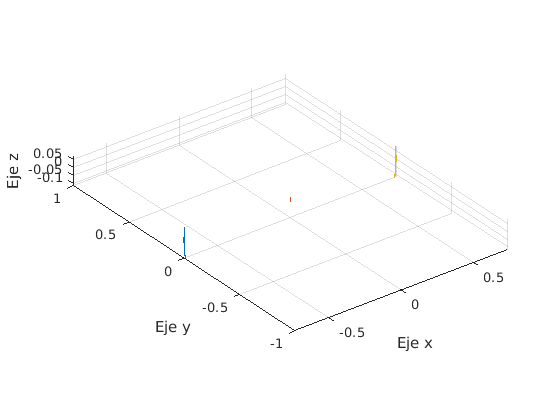

% Obtenemos una representación gráfica con los valores de X,Y y Z de los 3 nodos
% estudiados de la barra

% Realizar para cada simulatiom step para mostrar las diferencias

plot3(posiciones_nodo_0(:,1),posiciones_nodo_0(:,2),posiciones_nodo_0(:,3))
xlabel('Eje x') 
ylabel('Eje y') 
zlabel('Eje z') 
axis equal
hold on
grid on
plot3(posiciones_nodo_28(:,1),posiciones_nodo_28(:,2),posiciones_nodo_28(:,3))
plot3(posiciones_nodo_56(:,1),posiciones_nodo_56(:,2),posiciones_nodo_56(:,3))
hold off

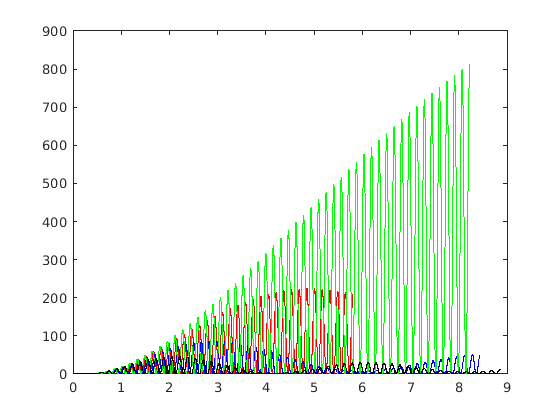


% Realizar estudio de las frecuencias obteniendo las gráficas de
% desplazamientos y maximos y mínimos

% Realizar estudio energético a distintas frecuencias

% Realizar estudio energético para la frecuencia de resonancia

[vector_tiempo5,Ecin5] = readvars('Energy_wcin_18.5.txt');
[vector_tiempo1,Ecin1] = readvars('Energy_wcin_19.5.txt');
[vector_tiempo2,Ecin2] = readvars('Energy_wcin_19.txt');
[vector_tiempo3,Ecin3] = readvars('Energy_wcin_20.txt');
[vector_tiempo4,Ecin4] = readvars('Energy_wcin_20.5.txt');
plot(vector_tiempo1,Ecin1,'r')
plot(vector_tiempo2,Ecin2,'b')
plot(vector_tiempo3,Ecin3,'g')
plot(vector_tiempo5,Ecin5,'k')

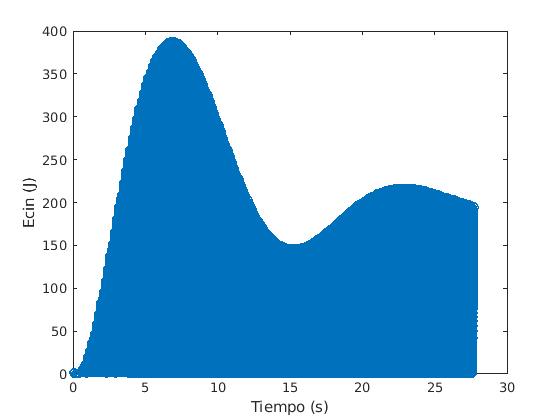

plot(vector_tiempo4,Ecin4,'o')
xlabel('Tiempo (s)')
ylabel('Ecin (J)')